
Y=X';


%PCA of the data upto 2 componets
pca(Y,"NumComponents",2)

ans =    -0.2367   -0.4419
   -0.3196   -0.3424
    0.0863   -0.1074
   -0.1825    0.1362
   -0.1673    0.4473
    0.1898   -0.0366
    0.6393    0.0806
   -0.2737   -0.3267
   -0.4995    0.4284
    0.0630   -0.3990


Var=cov(Y);
[U,S,V]=svd(Var);
center=mean(Y);

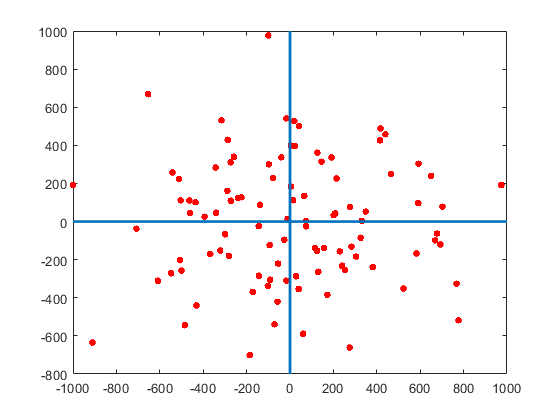

U1 = U(:,1:2);
Z=U1'*X;
%Projection the original data to the first two principal dimensions
plot(Z(1,:), Z(2,:), '.', 'markersize', 15,"Color","r")
xL = xlim;
yL = ylim;
line([0 0], yL,"linewidth",2);  
line(xL, [0 0],"linewidth",2); 

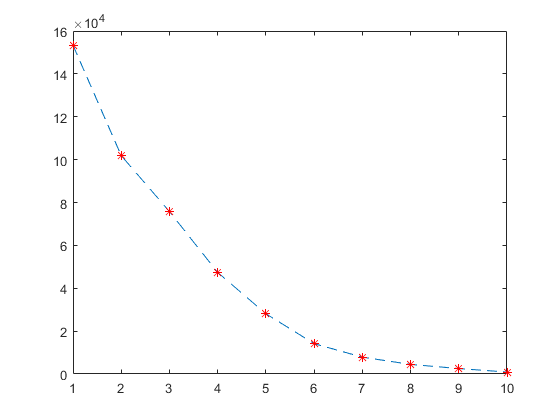

%singular value plot
plot(diag(S),"LineStyle","--","Marker","*","MarkerEdgeColor","r")

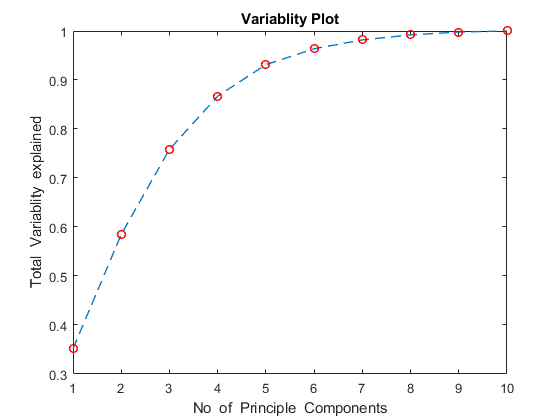

Splot=cumsum(diag(S))/sum(diag(S));
%cumulative  total variance plot
plot(Splot,"Marker","o","MarkerEdgeColor","r","LineWidth",1,"LineStyle","--")
title("Variablity Plot")
xlabel("No  of  Principle  Components")
ylabel("Total  Variablity  explained")